dataFolder = '/GEE_30m';
labelIDs = [0 1];
pixelLabelIDs = {0 1};
classes = ["no_label", "flood"];

imgDir = fullfile(pwd, dataFolder, '/train', 'images');
imds = imageDatastore(imgDir);

floodLabelSmoothThreshold = 0.3;
sigma = 4;
labelDir = fullfile(pwd, dataFolder, '/train', 'labels');
labelFcn = @(filename) customlabelreader(filename, floodLabelSmoothThreshold, sigma);
pxds = pixelLabelDatastore(labelDir, classes, pixelLabelIDs, 'ReadFcn',labelFcn);

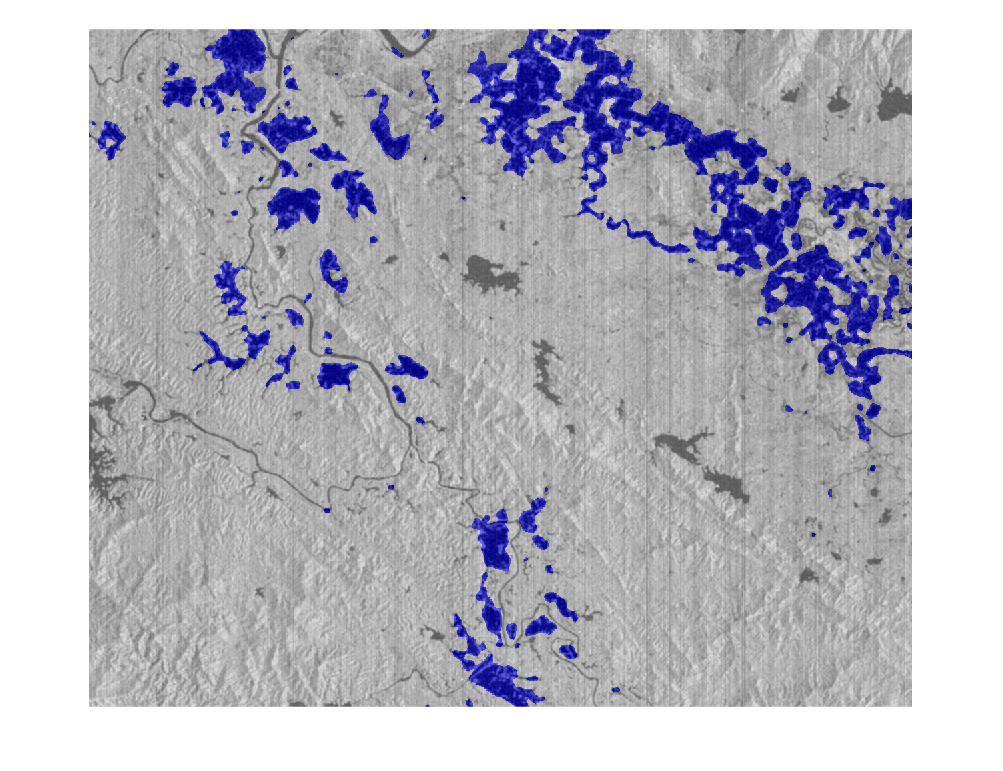

i = readimage(imds, 1);
c = readimage(pxds, 1);
i1 = normalize(i(:,:,1), 'range', [0 1]);
c1 = double(c);
b = labeloverlay(i1,c1,'ColorMap', [0.7 0.7 0.7; 0 0 1]);
imshow(b);

tbl = countEachLabel(pxds)

tbl = 2×3 table
        Name        PixelCount    ImagePixelCount
    ____________    __________    _______________

    {'no_label'}    3.3572e+07      3.5297e+07   
    {'flood'   }    1.7249e+06      3.5297e+07   


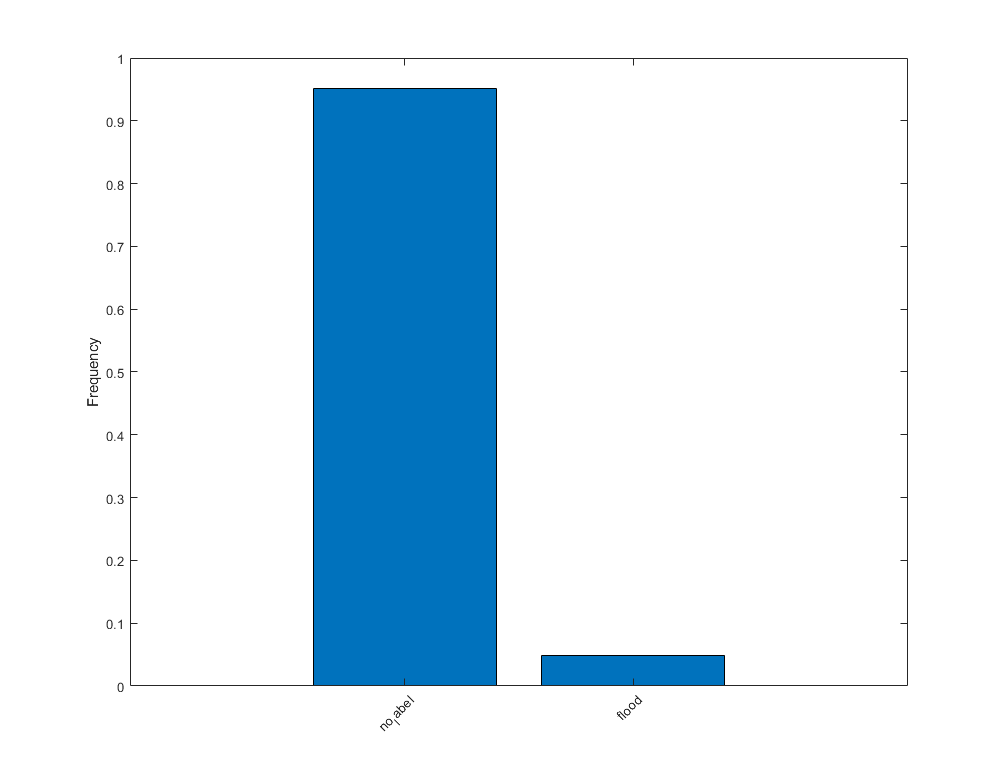

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

% imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
% classWeights = median(imageFreq) ./ imageFreq

inputTileSize = [256, 256, 2];
patchesPerImage = 400;
biasThreshold = 0.9;

augmenter = imageDataAugmenter("RandRotation",[-90, 90], ...
    "RandYTranslation", [-10 10], ...
    'RandXTranslation', [-10 10], ...
    "RandXReflection", true);
dsTrain = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), biasThreshold, 100, "PatchesPerImage", patchesPerImage, 'DataAugmentation', augmenter);
inputBatch = preview(dsTrain);
disp(inputBatch)

        InputImage        ResponsePixelLabelImage
    __________________    _______________________

    {256×256×2 double}     {256×256 categorical} 
    {256×256×2 double}     {256×256 categorical} 
    {256×256×2 double}     {256×256 categorical} 
    {256×256×2 double}     {256×256 categorical} 
    {256×256×2 double}     {256×256 categorical} 
    {256×256×2 double}     {256×256 categorical} 
    {256×256×2 double}     {256×256 categorical} 
    {256×256×2 double}     {256×256 categorical} 



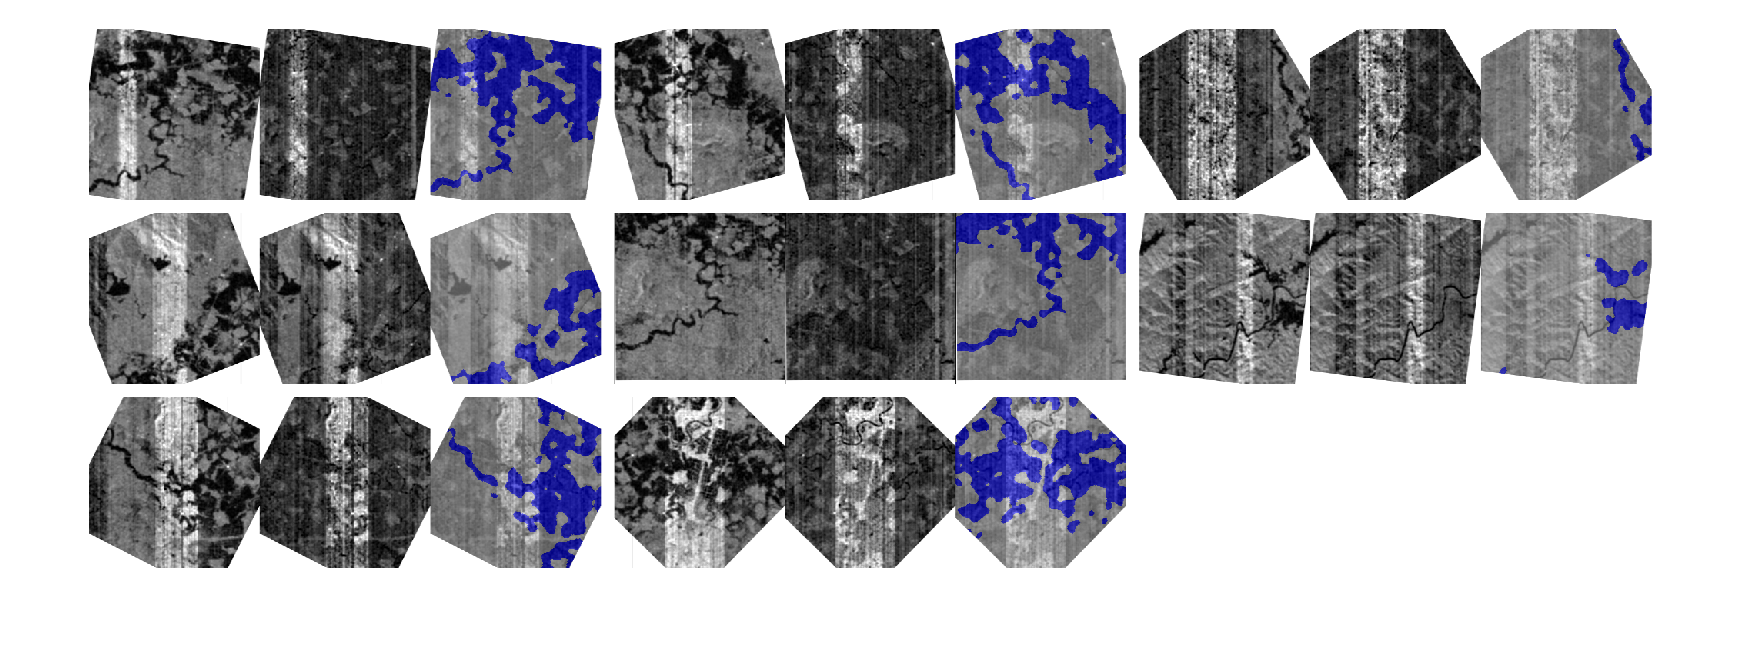

showImageWithLabel(inputBatch)

valImgDir = fullfile(pwd, dataFolder, '/validate', 'images');
valImds = imageDatastore(valImgDir);
valLabelDir = fullfile(pwd, dataFolder, '/validate', 'labels');
valPxds = pixelLabelDatastore(valLabelDir, classes, pixelLabelIDs);
dsValidate = imbalanceRandomPatchExtractionDatastore(imds, pxds, inputTileSize(1:2), biasThreshold, 1000, "PatchesPerImage", patchesPerImage,'DataAugmentation', augmenter);

% pxLayer = dicePixelClassificationLayer('Name','dice-Pixel-Classification-Layer','Classes',tbl.Name);
pxLayer = pixelClassificationLayer('Name','Pixel-Classification-Layer','Classes',tbl.Name);%,'ClassWeights',classWeights);
lgraph = createUnet(inputTileSize, numel(classes), pxLayer);
% lgraph = unetLayers(inputTileSize, numel(classes), "EncoderDepth", 4, "FilterSize",3);
% lgraph = replaceLayer(lgraph, 'Segmentation-Layer', pxLayer);
disp(lgraph.Layers)

initialLearningRate = 0.005;
maxEpochs = 100;
minibatchSize = 12;
l2reg = 0.0001;

options = trainingOptions('sgdm',...
    'InitialLearnRate',initialLearningRate,...
    'ValidationData', dsValidate,...
    'Momentum',0.9,...
    'L2Regularization',l2reg,...
    'MaxEpochs',maxEpochs,...
    'MiniBatchSize',minibatchSize,...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropFactor', 0.1,...
    'LearnRateDropPeriod', 5,...
    'Shuffle','every-epoch',...
    'GradientThresholdMethod','l2norm',...
    'GradientThreshold',6,...
    'Plots','training-progress',...
    'VerboseFrequency',20,...
    "ExecutionEnvironment","gpu");
%     "CheckpointPath", strcat(pwd, dataFolder, '/checkpoint'));

doTraining = true;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    [net,info] = trainNetwork(dsTrain,lgraph,options);
%     save(['savedUnet-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net','options');
end

Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


Error using trainNetwork (line 183)
The data no longer exists on the device.

Caused by:
    Error using nnet.internal.cnngpu.reluForward
    The data no longer exists on the device.